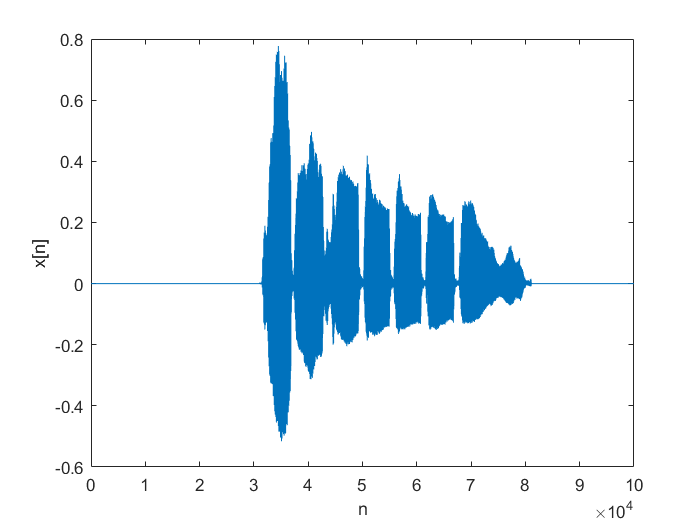

clear all;  
close all;
clc;

[file_1, dS_1] = audioread("trumpet.wav");
[file_2, fs_2] = audioread('telephoneIR.wav');

plot(file_1);
xlabel('n');
ylabel('x[n]');

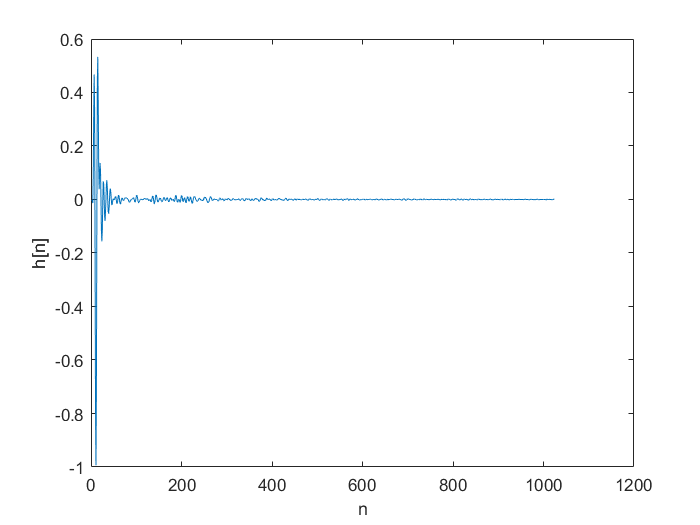

plot(file_2);
xlabel('n');
ylabel('h[n]');

tic;
ouput_signal_by_direct = my_direct_convolution(file_1, file_2);
toc;

Elapsed time is 0.424215 seconds.


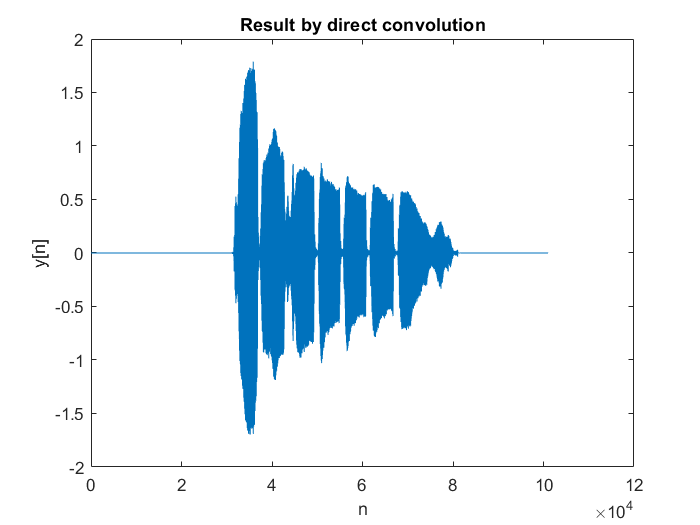

plot(ouput_signal_by_direct);
xlabel('n');
ylabel('y[n]');
title('Result by direct convolution');


L = length(file_1);
number_of_pad = 2.^ceil(log2(L));
tic;
output_signal_by_fft = my_fft_convolution(file_1, file_2, 101023);
toc;

Elapsed time is 0.199825 seconds.


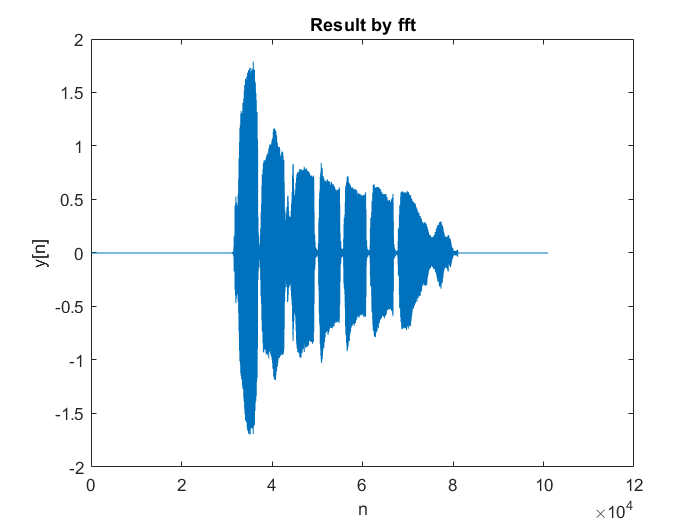

plot(output_signal_by_fft);
xlabel('n');
ylabel('y[n]');
title('Result by fft');


toc;

Elapsed time is 0.602745 seconds.


output_signal_by_blocks = my_fast_convolution(file_1, file_2);
toc;

Elapsed time is 0.744123 seconds.


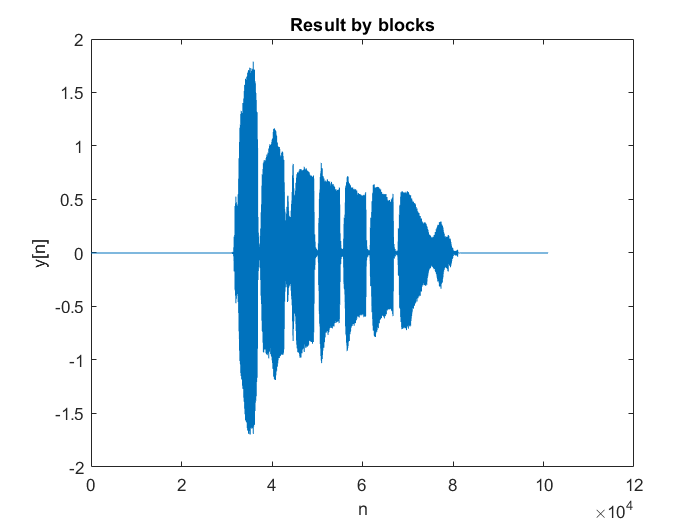

plot(output_signal_by_blocks);
xlabel('n');
ylabel('y[n]');
title('Result by blocks');

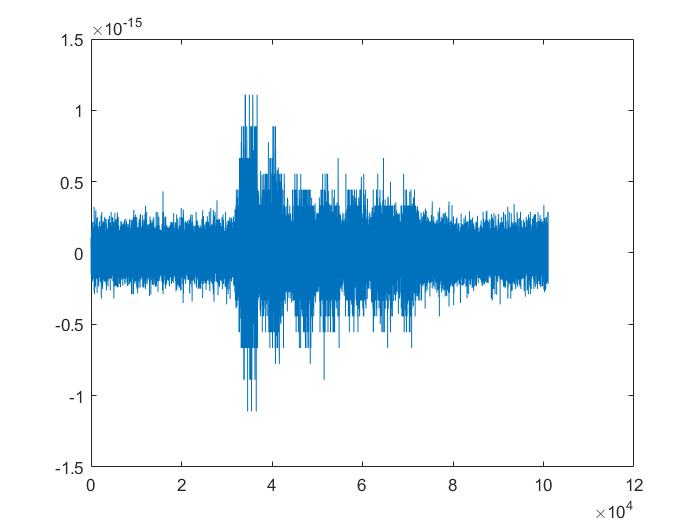


plot(output_signal_by_blocks' - output_signal_by_fft)